couple_all = {};

for recID = [3,6,9,12,19]

clearvars -except data_all recID couple_all

ParDir = 'Z:\users\Tatsumi\data\MultiReward'; % parent directory
recListPath = 'H:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Multireward_exp_list_2024.xlsx'; % table of rec info
allRecs = GetRecList(recListPath); % load the rec info list

GbFigDir = 'F:\Data\GroupForaging\Analysis\figure';
%% 240207
% recID = 3;
%% 240208
% recID = 6;
%% 240209_1
% recID = 9;
%% 240210_1
% recID = 12;
%% 240212
% recID = 19;

% general information
expType = allRecs.expType{recID}; % experiment type: social/solo/tethered
rewardType = allRecs.rewardType{recID}; % reward type: multi/single flavor
rootdir = fullfile(ParDir,allRecs.rootdir{recID}); % root directory of the recording
ephysDir = fullfile(rootdir,'ephys',allRecs.ephysDir{recID}); % ephys directory
recDate = char(allRecs.date(recID),'MM/dd/yy'); % date of recording
recName = allRecs.recName{recID};
bname_ephys = allRecs.ephysBat{recID}; % name of ephys bat
probeNum = allRecs.probeNum(recID); % probe number
trjName = allRecs.trjName{recID}; % trajectory

corr_th = 2;

% GenDir = 'F:\Data\GroupForaging\Analysis\figure\Firing_deviation\deviation_xcorr_2std_allUnits\Ephys14633_MEC_2';
FigDir = fullfile(GbFigDir,'Firing_deviation',sprintf('deviation_xcorr_%dstd_allUnits',corr_th), ...
    sprintf('Ephys%s_%s',bname_ephys,trjName), ...
    recName);
load(fullfile(FigDir,'xcorr_deviation.mat'))


rec_now = strcmp(data_all(:,1),recName);
celltype = data_all(rec_now,4);
self_land = logical(cell2mat(data_all(rec_now,6)));
self_toff = logical(cell2mat(data_all(rec_now,7)));

other_land = logical(cell2mat(data_all(rec_now,8)));
other_toff = logical(cell2mat(data_all(rec_now,9)));

self_social = self_land | self_toff;
other_social = other_land | other_toff;

n_unit = length(celltype);
unit_pair = nchoosek(1:n_unit,2);
for pair = 1:size(unit_pair,1)
    unit1 = unit_pair(pair,1); unit2 = unit_pair(pair,2);

    if self_social(unit1) && self_social(unit2)
        xcorr_deviation{pair,10} = 'self: social vs social';
    elseif ~self_social(unit1) && ~self_social(unit2)
        xcorr_deviation{pair,10} = 'self: nonsocial vs nonsocial';
    else
        xcorr_deviation{pair,10} = 'self: social vs nonsocial';
    end

    if other_social(unit1) && other_social(unit2)
        xcorr_deviation{pair,11} = 'other: social vs social';
    elseif ~other_social(unit1) && ~other_social(unit2)
        xcorr_deviation{pair,11} = 'other: nonsocial vs nonsocial';
    else
        xcorr_deviation{pair,11} = 'other: social vs nonsocial';
    end

    if strcmp(celltype{unit1},'Interneuron') && strcmp(celltype{unit2},'Interneuron')
        xcorr_deviation{pair,12} = 'Interneuron vs Interneuron';
    elseif strcmp(celltype{unit1},'Excitatory') && strcmp(celltype{unit2},'Excitatory')
        xcorr_deviation{pair,12} = 'Excitatory vs Excitatory';
    else
        xcorr_deviation{pair,12} = 'Excitatory vs Interneuron';
    end
end

couple_all = [couple_all; xcorr_deviation];

end

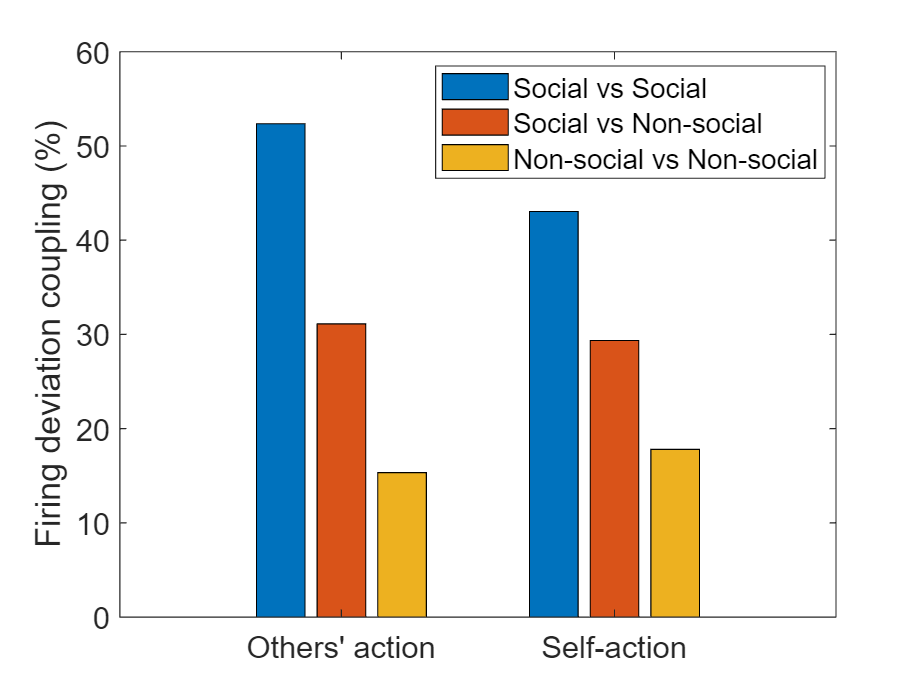

x = categorical({'Self-action','Others'' action'});
y = zeros(2,3);

unique(couple_all(:,10));
idx = strcmp(couple_all(:,10),'self: social vs social');
y(1,1) = sum(cell2mat(couple_all(idx,9))) / sum(idx) * 100;
idx = strcmp(couple_all(:,10),'self: social vs nonsocial');
y(1,2) = sum(cell2mat(couple_all(idx,9))) / sum(idx) * 100;
idx = strcmp(couple_all(:,10),'self: nonsocial vs nonsocial');
y(1,3) = sum(cell2mat(couple_all(idx,9))) / sum(idx) * 100;

idx = strcmp(couple_all(:,11),'other: social vs social');
y(2,1) = sum(cell2mat(couple_all(idx,9))) / sum(idx) * 100;
idx = strcmp(couple_all(:,11),'other: social vs nonsocial');
y(2,2) = sum(cell2mat(couple_all(idx,9))) / sum(idx) * 100;
idx = strcmp(couple_all(:,11),'other: nonsocial vs nonsocial');
y(2,3) = sum(cell2mat(couple_all(idx,9))) / sum(idx) * 100;

figure
bar(x,y)
ylabel('Firing deviation coupling (%)')
ylim([0,60])
legend({'Social vs Social','Social vs Non-social','Non-social vs Non-social'},'Location','best')
set(gca,'FontSize',14)

y

y =    43.0380   29.3466   17.7981
   52.3546   31.1206   15.3308


sum(cell2mat(couple_all(:,9)))

ans = 985

sum(cell2mat(couple_all(:,9))) / size(couple_all,1)

ans = 0.2550